# Example 13.2 - Torque-free motion of a spacecraft

A rigid spacecraft with principal moments of inertia $J_{xx}$= 4000 $kg.m^2$, $J_{yy}$ = 7500 $kg.m^2$, $J_{zz}$ = 8500 $kg.m^2$ has an initial angular velocity $\omega(0)$=(0.1, -0.2, 0.5) rad/s and an initial attitude $\psi(0)=0$, $\theta(0)=\frac{\pi}{2}$, $\phi(0)=0$. Simulate the subsequent rotation of the spacecraft

[t,x]=ode45(@spacerotation,[0 40],[0.1 -0.2 0.5 0 0.5*pi 0]');

ok
ok
ok


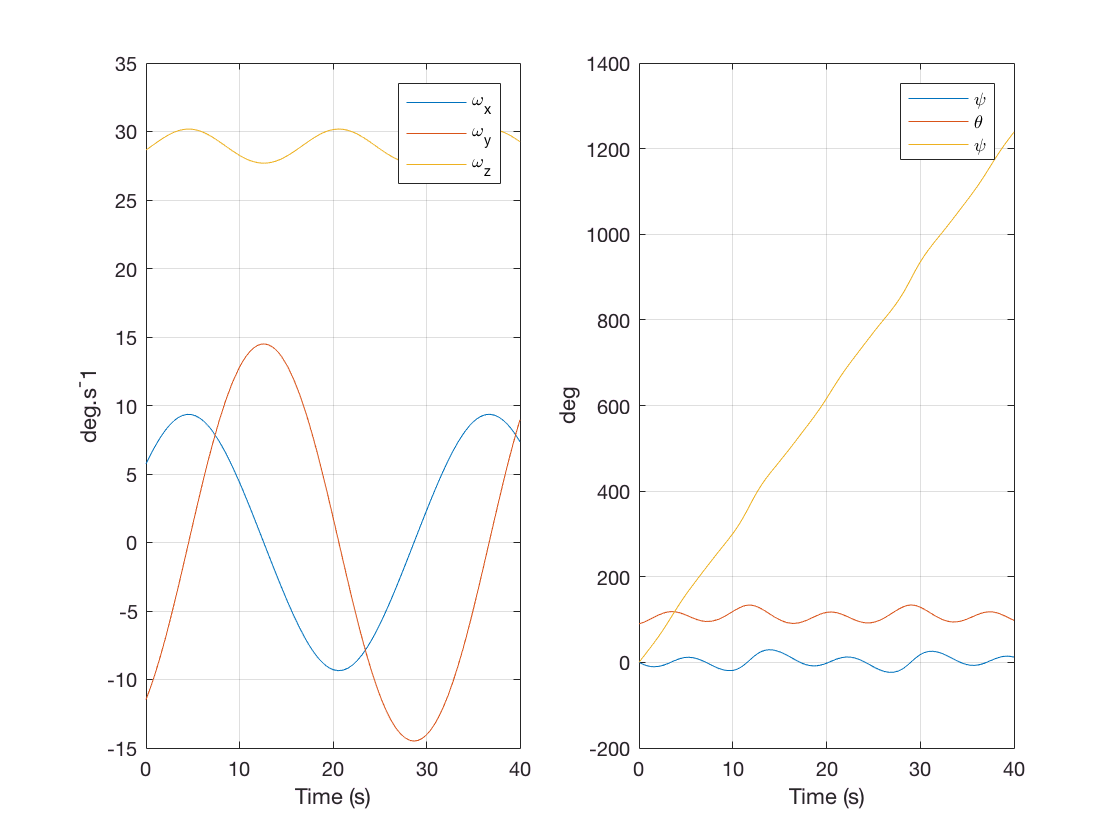

subplot(121),plot(t,x(:,1:3)*180/pi),grid on;
xlabel('Time (s)');ylabel('deg.s^-1');legend('\omega_x','\omega_y','\omega_z');
subplot(122),plot(t,x(:,4:6)*180/pi),grid on;
xlabel('Time (s)');ylabel('deg');legend('\psi','\theta','\psi');